clear;clc;

csvFile = 'csvHeadersEx.csv';
xlsmFile = 'xlsmHeadersEx.xlsm';
myFig = uifigure;

% tcsv = readtable(csvFile,...
%     ReadVariableNames= true, VariableNamingRule= 'preserve');
% try sheetnames(spdFileFullPath)
%     uialert(myFig, "File has multiple sheets. Loading Sheet 1", "Warning",'icon','warning');
% 
% catch
%     disp("No sheetnames")
% end
% uitable(myFig,'Data',tcsv)


txlsm = readtable(xlsmFile,...
    ReadVariableNames= true, VariableNamingRule= 'preserve');
try sheetnames(xlsmFile)
    uialert(myFig, "File has multiple sheets. Loading Sheet 1", "Warning",'icon','warning');

catch
    disp("No sheetnames")
end

ans = 2×1 string array
    "csvHeadersEx"
    "Sheet1"


uit = uitable(myFig)

uit =   Table with properties:

                Data: []
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [20 20 300 300]
               Units: 'pixels'

  Show all properties


uit.ColumnName=[];
uit.Data = txlsm

uit =   Table with properties:

                Data: [6×12 table]
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [20 20 300 300]
               Units: 'pixels'

  Show all properties


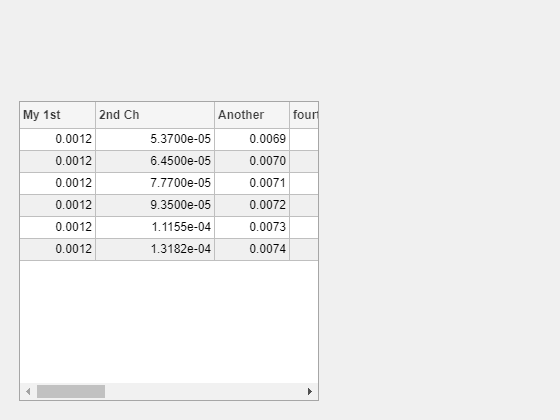

uit =   Table with properties:

                Data: [6×12 table]
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [20 20 300 300]
               Units: 'pixels'

  Show all properties


uit.ColumnName = txlsm.Properties.VariableNames